# Signal Processing

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2019-01-06

### Example: Square Wave

clear; clc ; close all;

% this signal is assumed to be analog. 
ncyle = 3;
Fsa = 1000; % # of samples per a second (assumed to be infinite)
Tp = 2;
t = -ncyle*Tp:1/Fsa:ncyle*Tp;
x = @(t) square(t*(2*pi)/Tp); % original signal


$$x\left(t\right)=\frac{a_0 }{2}+\sum_{n=0}^{\infty } a_n \mathrm{cos}\left(\frac{2\pi \mathrm{nt}}{T_p }\right)+b_n \mathrm{sin}\left(\frac{2\pi \mathrm{nt}}{T_p }\right)$$


a0 = integral(x, -Tp/2, Tp/2);

nCoeff = 5;
a = zeros(nCoeff,1);
b = zeros(nCoeff,1);
sig_y_numeric = zeros(nCoeff, numel(t));
sig_y_analytic = zeros(nCoeff, numel(t));
for ii=1:nCoeff
    fun_a = @(t) x(t).*cos(2*pi*ii*t/Tp);
    a(ii) = integral(fun_a, -Tp/2, Tp/2);
    
    fun_b = @(t) x(t).*sin(2*pi*ii*t/Tp);
    b(ii) = integral(fun_b, -Tp/2, Tp/2);
    
    if ii==1
        sig_y_numeric(ii,:) = a0 + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    else
        sig_y_numeric(ii,:) = sig_y_numeric(ii-1,:) + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    end
    sig_y_analytic(ii,:) = x_analytic(t, Tp, ii);
end



$$x\left(t\right)=\sum_{n=0}^{\infty } \frac{2}{n\pi }\left(1-\mathrm{cosn}\pi \right)\sin \left(\frac{2\pi \textrm{nt}}{T_p }\right)$$


% function x = x_analytic (t, Tp, n)
% 
% x = zeros(1, numel(t));
% for ii=1:n
%     x = x + 2/(ii*pi)*(1-cos(ii*pi))*sin(2*pi*ii*t/Tp);
% end


fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(221); plot(t,x(t),'-b', 'linewidth', 2);
axis tight;grid on;
title('Square wave, x(t)')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(222); plot(t,sig_y_numeric(1,:),'-b', 'linewidth', 2); hold on;
plot(t,sig_y_analytic(1,:),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 1 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('Analytic', 'Numeric');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(223); plot(t,sig_y_numeric(3,:),'-b', 'linewidth', 2); hold on;
plot(t,sig_y_analytic(3,:),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 3 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('Analytic', 'Numeric');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(224); plot(t,sig_y_numeric(nCoeff,:),'-b', 'linewidth', 2); hold on;
plot(t,sig_y_analytic(nCoeff,:),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 5 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('Analytic', 'Numeric');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Example: Square Wave (Complex Form)

clear; clc ; close all;

% this signal is assumed to be analog. 
ncyle = 3;
Fsa = 1000; % # of samples per a second (assumed to be infinite)
Tp = 2;
t = -ncyle*Tp:1/Fsa:ncyle*Tp;
x = @(t) square(t*(2*pi)/Tp); % original signal

a0 = integral(x, -Tp/2, Tp/2);

nCoeff = 5;
a = zeros(nCoeff,1);
b = zeros(nCoeff,1);
sig_y_general = zeros(nCoeff, numel(t));
for ii=1:nCoeff
    fun_a = @(t) x(t).*cos(2*pi*ii*t/Tp);
    a(ii) = integral(fun_a, -Tp/2, Tp/2);
    
    fun_b = @(t) x(t).*sin(2*pi*ii*t/Tp);
    b(ii) = integral(fun_b, -Tp/2, Tp/2);
    
    if ii==1
        sig_y_general(ii,:) = a0 + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    else
        sig_y_general(ii,:) = sig_y_general(ii-1,:) + a(ii)*cos(2*pi*ii*t/Tp) + b(ii)*sin(2*pi*ii*t/Tp);
    end
end


$$x\left(t\right)=\sum_{n=-\infty }^{\infty } c_n e^{\mathrm{i2}\pi \mathrm{nt}/T_p }$$


sig_y_complex_all = zeros(2*nCoeff+1, numel(t));
count = 1;
for ii=-nCoeff:nCoeff
    fun = @(t) x(t).*exp(-sqrt(-1)*2*pi*ii*t/Tp);
    sig_y_complex_all(count,:) = 1/Tp* integral(fun, 0, Tp)*exp(sqrt(-1)*2*pi*ii*t/Tp);
    count = count + 1;
end

sig_y_complex = zeros(nCoeff, numel(t));
for ii=1:nCoeff
    rowId = (nCoeff-ii+1):(nCoeff+ii+1);
    sig_y_complex(ii,:) = sum(sig_y_complex_all(rowId,:));
end

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(221); plot(t,x(t),'-b', 'linewidth', 2);
axis tight;grid on;
title('Square wave, x(t)')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(222); plot(t,sig_y_general(1,:),'-b', 'linewidth', 2); hold on;
plot(t,real(sig_y_complex(1,:)),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 1 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('General', 'Complex');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(223); plot(t,sig_y_general(3,:),'-b', 'linewidth', 2); hold on;
plot(t,real(sig_y_complex(3,:)),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 3 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('General', 'Complex');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(224); plot(t,sig_y_general(nCoeff,:),'-b', 'linewidth', 2); hold on;
plot(t,real(sig_y_complex(nCoeff,:)),':r', 'linewidth', 2);
axis tight;grid on; hold off;
title('Use 5 coeefficient')
ylabel('\bf Amplitude'); ylim([-1.5 1.5]);
xlabel('\bf Time (sec)');
legend('General', 'Complex');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Sinc Function

clear; close all; clc;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

t = -2:0.01:2 + realmin;
M = 1;
y = sin(2*pi*t*M)./(2*pi*M*t);
subplot(121); plot(t,y,'-b', 'linewidth', 2);
hold on; plot(1/M,0,'or', 'linewidth', 4); hold off;
legend('Sinc func', '1/M (M=1)')
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


t = -2:0.01:2 + realmin;
M = 3;
y = sin(2*pi*t*M)./(2*pi*M*t);
subplot(122); plot(t,y,'-b', 'linewidth', 2);
hold on; plot(1/M,0,'or', 'linewidth', 4); hold off;
legend('Sinc func', '1/M (M=3)')
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf Time (sec)');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (**Exponentially Decaying Symmetric Function)**

clear; close all; clc;

lambda = 3;
x = @(t) exp(-lambda.*abs(t));
x_in = @(t, f) x(t)*exp(-sqrt(-1)*2*pi*f*t);
Xf = @(f) integral(@(t) x_in(t, f), -inf, inf,'ArrayValued',true);
Xf_analytic = @(f) 2*lambda./(lambda^2 + 4*pi*pi.*f.*f);
t = -3:0.01:3;
f = -3:0.01:3;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,real(Xf(f)),'-b', 'linewidth', 2);
hold on; plot(f,Xf_analytic(f),':r', 'linewidth', 2);
plot(0, 2/lambda,'or', 'linewidth', 4); hold off;
legend('X(f)-n','X(f)-a', '2/\lambda');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (Rectangular Function**)**

clear; close all; clc;

a = 3;
b = 4;

x = @(t) a*(abs(t)<=b) + 0;
x_in = @(t, f) x(t)*exp(-sqrt(-1)*2*pi*f*t);
Xf = @(f) integral(@(t) x_in(t, f), -b, b,'ArrayValued',true);
Xf_analytic = @(f) 2*a*b*sin(2*pi*f*b)/(2*pi*f*b);

t = -6:0.01:6;
f = [-3:0.01:3] +realmin;

fig5 = figure(5);
set(fig5,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-a*0.1 a*1.1]);
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,real(Xf(f)),'-b', 'linewidth', 2);
hold on; plot(0, 2*a*b,'or', 'linewidth', 4); 
plot(f,Xf_analytic(f),':r', 'linewidth', 2);
legend('X(f)-n','2*a*b','X(f )-a');hold off;
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (**Damped Symmetrically Oscillating Function)**

clear; close all; clc;

a = 3;
f_0 = 4;

x = @(t) exp(-a.*abs(t)).*cos(2*pi*f_0*t);
x_in = @(t, f) x(t)*exp(-sqrt(-1)*2*pi*f*t);
Xf = @(f) integral(@(t) x_in(t, f), -inf, inf,'ArrayValued',true);

Xf_analytic = @(f) a./(a^2+(2*pi*(f-f_0)).^2) + a./(a^2+(2*pi*(f+f_0)).^2);

t = -2:0.01:2;
f = [-12:0.01:12] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(f,real(Xf(f)),'-b', 'linewidth', 2);
hold on; plot(f,Xf_analytic(f),':r', 'linewidth', 2);
plot([-f_0 f_0], [0 0],'or', 'linewidth', 4); hold off;
legend('X(f)-n','X(f)-a', 'f_0');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Fourier Transform Pairs (Gaussian** Function)**

clear; close all; clc;

a = 5;

x = @(t) exp(-a.*t.*t);
x_in = @(t, w) x(t)*exp(-sqrt(-1)*w*t);
Xw = @(w) integral(@(t) x_in(t, w), -inf, inf,'ArrayValued',true);
Xw_analytic = @(w) sqrt(pi/a).*exp(-w.*w/(4*a));

t = -2:0.01:2;
w = [-12:0.01:12] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 300]);

subplot(121);plot(t,x(t),'-b', 'linewidth', 2);
legend('x(t)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf t');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(122);plot(w,real(Xw(w)),'-b', 'linewidth', 2);
hold on; plot(w,Xw_analytic(w),':r', 'linewidth', 2);
plot(0, sqrt(pi/a),'or', 'linewidth', 4); hold off;
legend('X(w)-n','X(w)-a', '(\pi / a)^{(1/2)}');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf w');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


### Convotluion 1

clear; clc ; close all;

syms t   

a = 3; b = 3;
sig1 = @(t) a*(abs(t)<=b) + 0;

a = 2; b = 1;
sig2 = @(t) a*(abs(t)<=b) + 0;

t = -10:0.01:10;

fig1 = figure(1);
set(fig1,'Position', [100 100 800 900]);

subplot(411); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(t),'-r', 'linewidth', 2);
legend('sig1', 'sig2'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-5 5])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(412); plot(t,sig1(t).*sig2(t),'-b', 'linewidth', 2);hold on;
legend('sig1 x sig2'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 7])
xlabel('\bf Time');xlim([-5 5])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

fig2 = figure(2);
set(fig2,'Position', [100 100 800 900]);

sig_conv = conv(sig1(t), sig2(t))*0.01;
subplot(411); plot(t,sig_conv((floor(numel(sig_conv)/4)):floor(numel(sig_conv)/4)*3),'-b', 'linewidth', 2);hold on;
legend('sig1(t) * sig2(t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 14])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(412); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-4-t),':r', 'linewidth', 2);hold on;
legend('sig1(t)', 'sig2(-4-t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(413); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-3-t),':r', 'linewidth', 2);hold on;
legend('sig1(t)', 'sig2(-3-t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(414); plot(t,sig1(t),'-b', 'linewidth', 2);hold on;
plot(t,sig2(-2-t),':r', 'linewidth', 2);hold on;
legend('sig1(t)', 'sig2(-2-t)'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([0 4])
xlabel('\bf Time');xlim([-10 10])
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Convotluion 2

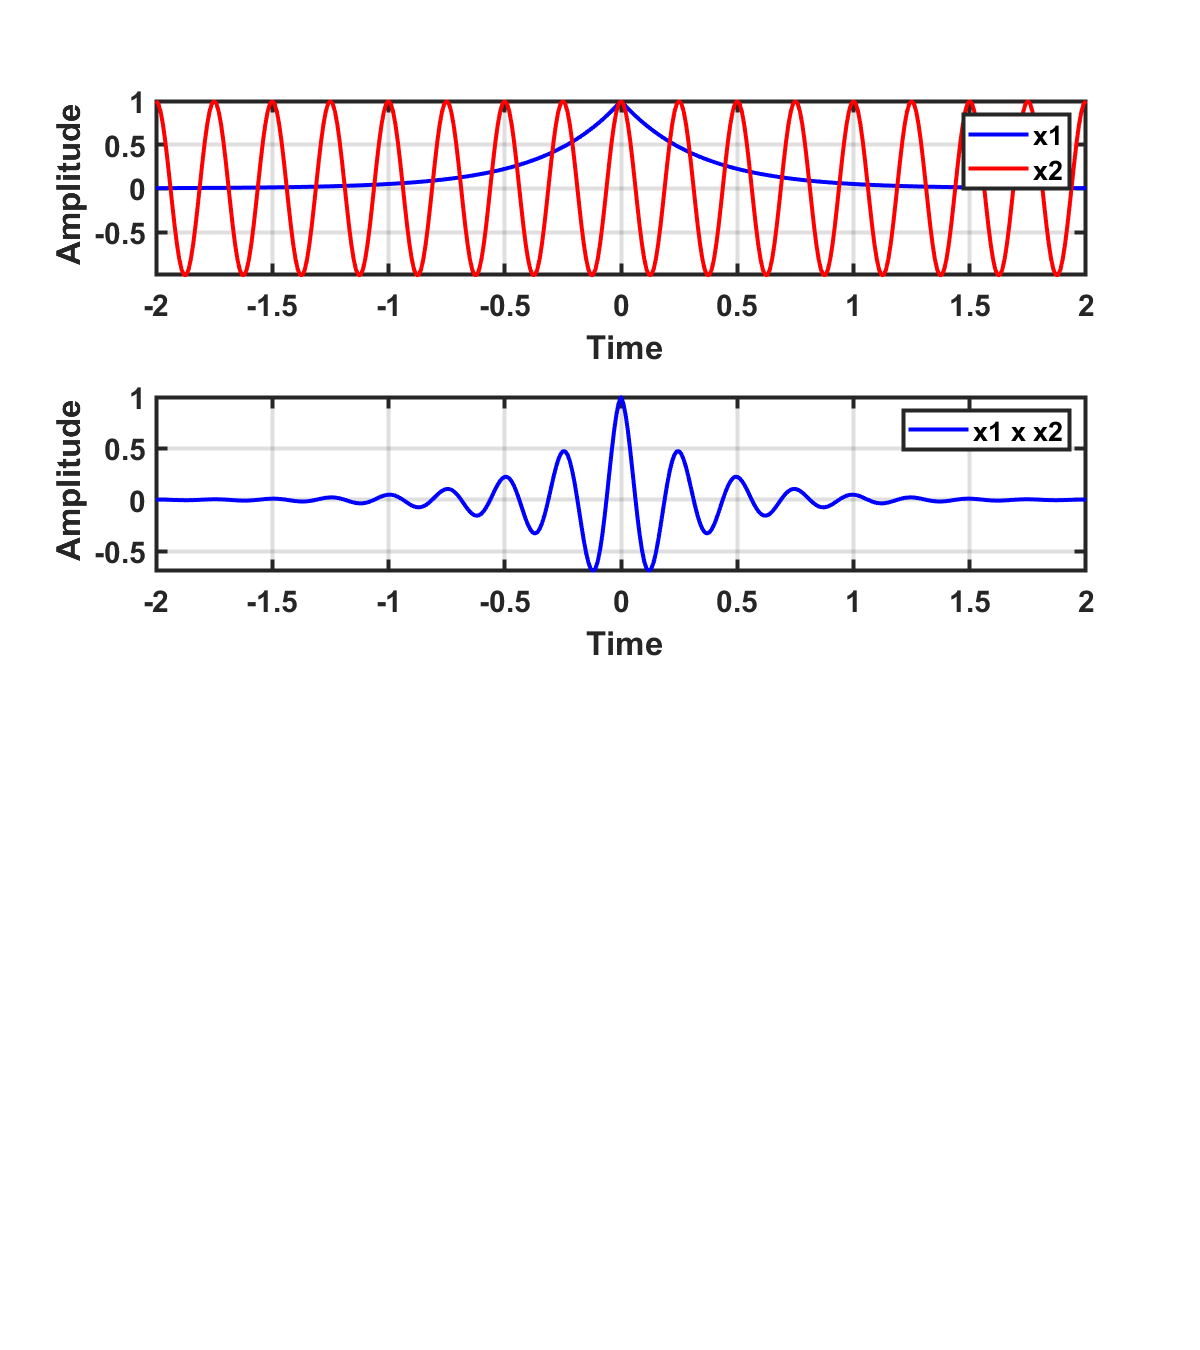

clear; clc ; close all;

a = 3;
f_0 = 4;

x1 = @(t) exp(-a.*abs(t));
x2 = @(t) cos(2*pi*f_0*t);

x3 = @(t) x1(t).*x2(t);

x1_in = @(t, f) x1(t)*exp(-sqrt(-1)*2*pi*f*t);
X1f = @(f) integral(@(t) x1_in(t, f), -inf, inf,'ArrayValued',true);

x2_in = @(t, f) x2(t)*exp(-sqrt(-1)*2*pi*f*t);
X2f = @(f) integral(@(t) x2_in(t, f), -inf, inf,'ArrayValued',true);

x3_in = @(t, f) x3(t)*exp(-sqrt(-1)*2*pi*f*t);
X3f = @(f) integral(@(t) x3_in(t, f), -inf, inf,'ArrayValued',true);

t = -2:0.01:2;
f = [-12:0.01:12] +realmin;

fig1 = figure(1);
set(fig1,'Position', [100 100 800 900]);

subplot(411); plot(t,x1(t),'-b', 'linewidth', 2);hold on;
plot(t,x2(t),'-r', 'linewidth', 2);
legend('x1', 'x2'); axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf Time');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

subplot(412); plot(t,x1(t).*x2(t),'-b', 'linewidth', 2);hold on;
legend('x1 x x2'); axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf Time');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');


fig2 = figure(2);
set(fig2,'Position', [100 100 800 900]);

subplot(121);plot(f,real(X1f(f)),'-b', 'linewidth', 2);
hold on; plot(f,real(X3f(f)),':r', 'linewidth', 2);
plot([-f_0 f_0], [0 0],'or', 'linewidth', 4); hold off;
legend('X1(f)','X2(f)');
axis tight;grid on;
ylabel('\bf Amplitude'); 
xlabel('\bf f');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

### Effects of Windowing on the Frequency Signal (Modulus)

clear; close all; clc;

T = 0.6;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig1 = figure(1);
set(fig1,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

T = 1;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig2 = figure(2);
set(fig2,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

T = 2;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig3 = figure(3);
set(fig3,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');


T = 4;
[sig, hann, rectw, fs] = hann_rect_window_example(T);

fig4 = figure(4);
set(fig4,'Position', [100 100 1300 300]);

subplot(131); plot(sig.t,sig.x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(132);stem(rectw.f(1:rectw.N/2+1), abs(rectw.X(1:rectw.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(rectw.fz(1:rectw.Nz/2+1), abs(rectw.Xz(1:rectw.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 1.2], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(133);stem(hann.f(1:hann.N/2+1), abs(hann.X(1:hann.N/2+1)/fs/T), 'r:', 'linewidth', 1); hold on;
plot(hann.fz(1:hann.Nz/2+1), abs(hann.Xz(1:hann.Nz/2+1)/fs/T), 'b', 'linewidth', 1)
line([10 10],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([20 20],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
line([21 21],[0 0.6], 'linewidth', 1, 'color', 'k','linestyle', ':');
axis tight;grid on; hold off;
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

### Zero-padding

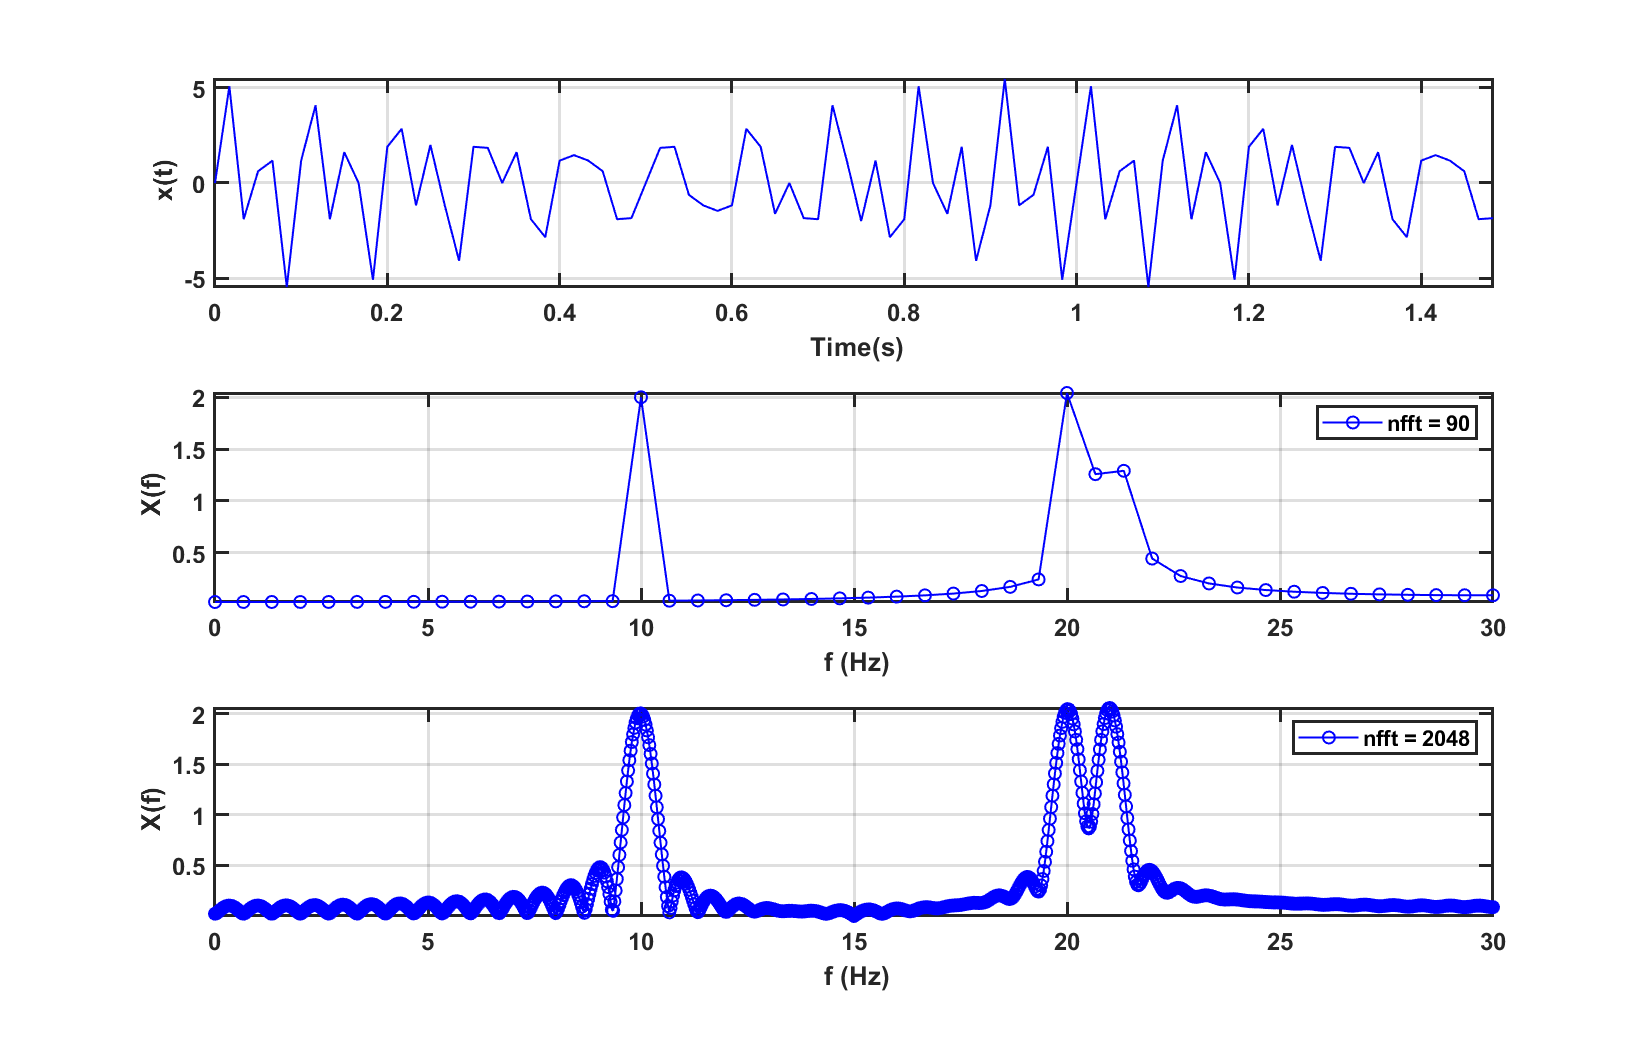

clear; close all; clc;

f1 = 10; f2=20; f3=21; 


fs=60; % sampling frequency

T = 1.5;
t = 0: 1/fs : T-1/fs;
x = 2*sin(2*pi*f1*t) + 2 * sin(2*pi*f2*t) + 2 * sin(2*pi*f3*t);

N = length(x);

wrect = rectwin(N);
xrect = x.*wrect';
X1 = fft(xrect);
f1 = fs*(0:N-1)/N;

fig2 = figure(2);
set(fig2,'Position', [100 100 1100 700]);

subplot(311); plot(t,x, 'b', 'linewidth', 1);
axis tight;grid on; hold off;
ylabel('\bf x(t)'); 
xlabel('\bf Time(s)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

subplot(312);plot(f1(1:N/2+1), 2*abs(X1(1:N/2+1)/fs/T), '-ob', 'linewidth', 1)
axis tight;grid on; hold off;
legend(sprintf('nfft = %d',N))
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');

nfft = 2048;
X2 = fft(xrect, nfft);
f2 = fs*(0:nfft-1)/nfft;

subplot(313);plot(f2(1:nfft/2+1), 2*abs(X2(1:nfft/2+1)/fs/T), '-ob', 'linewidth', 1)
axis tight;grid on; hold off;
legend(sprintf('nfft = %d',nfft))
ylabel('\bf X(f)'); 
xlabel('\bf f (Hz)');
set(gca,'fontsize',12,'linewidth',1.5,'fontweight','bold');